# Euler-Bernoulli beam solved with singular functions

Second moment loss (or elastic modulus) can be modelled with singular functions.

## Verification 

for simple supported beam with formulas from literature for beam without inhomogeneity.

Reference for verification:

Beate Bender, Dietmar Göhlich; Dubbel Taschenbuch für den Maschinenbau 1: Grundlagen und Tabellen; 26. Auflage; [https://doi.org/10.1007/978-3-662-59711-8;](https://doi.org/10.1007/978-3-662-59711-8;) 2020.

syms x F d_F L E I

### Equation in reference 

The conventional solution for Euler-Bernoulli beam can be only applied to homogenous material properties (EI=const)

(Note: Displacement coordinate points downwards in the reference)


$$w(x) = \begin{cases} 
     w(x) = - \frac{F d_F (L-d_F)^2}{6 E I} \left[ \left(1+ \frac{L}{L-d_F} \right) \frac{x}{L} - \frac{x^3}{d_F(L-d_F)L} \right] & 
          0\leq x\leq d_F \\
     w(x) = - \frac{F {d_F}^2 (L-d_F)}{6 E I} \left[ \left(1+ \frac{L}{d_F} \right) \frac{L-x}{L} - \frac{(L-x)^3}{d_F(L-d_F)L} \right] &  d_F \leq x\leq L
       \end{cases}$$


w_pw_lit=[-(F.*d_F .*(L-d_F).^2)./(6.*E.*I).*((1+L./(L-d_F)).*x./L - x.^3./(d_F.*(L-d_F).*L)); ...
       -(F.*d_F.^2 .*(L-d_F))./(6.*E.*I).*((1+L./d_F).*(L-x)./L - (L-x).^3./(d_F.*(L-d_F).*L))];
w_pw_lit=simplify(w_pw_lit);

cond_lit=[0<= x & x<= d_F; d_F< x & x<= L];

dw_pw_lit=simplify(diff(w_pw_lit,x));
ddw_pw_lit=simplify(diff(dw_pw_lit,x));


### Example

F_val=6; d_F_val=0.3;
I_val=1; E_val=1; 
L_val=1;
numOfPnts=21;
b_1_val=0.3;
b_2_val=0.5;

x_val=linspace(0,L_val,numOfPnts);

function

[w,dw,ddw] = oneFieldBeam(x_val, E_val, L_val, d_F_val, F_val, [I_val I_val], [b_1_val b_2_val]);

  w=double(  w);
 dw=double( dw);
ddw=double(ddw);

literature formulas

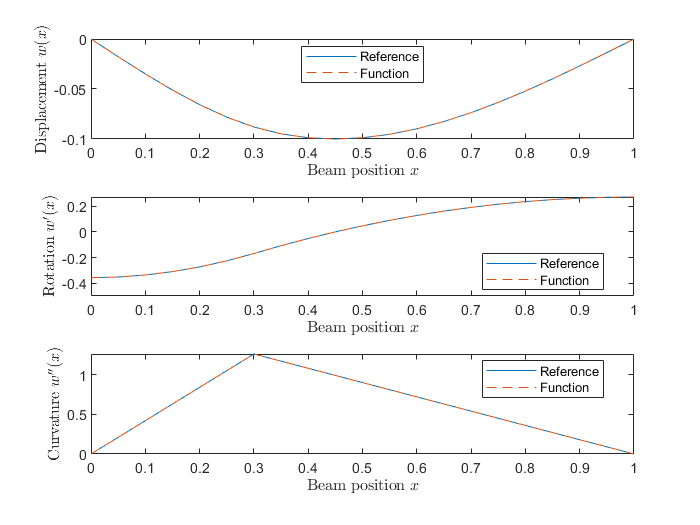

vars=[F      d_F      I      E      L      x];
vals={F_val  d_F_val  I_val  E_val  L_val  x_val};

  w_pw_lit_subs=double(subs(  w_pw_lit,vars,vals));
 dw_pw_lit_subs=double(subs( dw_pw_lit,vars,vals));
ddw_pw_lit_subs=double(subs(ddw_pw_lit,vars,vals));
cond_lit_sub=boolean(subs(cond_lit,vars,vals));
  w_lit_subs=sum(  w_pw_lit_subs.*cond_lit_sub,1);
 dw_lit_subs=sum( dw_pw_lit_subs.*cond_lit_sub,1);
ddw_lit_subs=sum(ddw_pw_lit_subs.*cond_lit_sub,1);

figure
%
subplot(3,1,1)
hold on
plot(x_val,w_lit_subs)
plot(x_val,w,'--')
legend('Reference','Function','Location','best')
xlabel('Beam position $x$','Interpreter','latex')
ylabel('Displacement $w(x)$','Interpreter','latex')
box on
%
subplot(3,1,2)
hold on
plot(x_val,dw_lit_subs)
plot(x_val,dw,'--')
legend('Reference','Function','Location','best')
xlabel('Beam position $x$','Interpreter','latex')
ylabel('Rotation $w^\prime(x)$','Interpreter','latex')
box on
%
subplot(3,1,3)
hold on
plot(x_val,ddw_lit_subs)
plot(x_val,ddw,'--')
legend('Reference','Function','Location','best')
xlabel('Beam position $x$','Interpreter','latex')
ylabel('Curvature $w^{\prime\prime}(x)$','Interpreter','latex')
box on


clearvars

## Different EI stages


$$E\;I\not= \textrm{const}$$


### One Field beam (Simple supported beam)

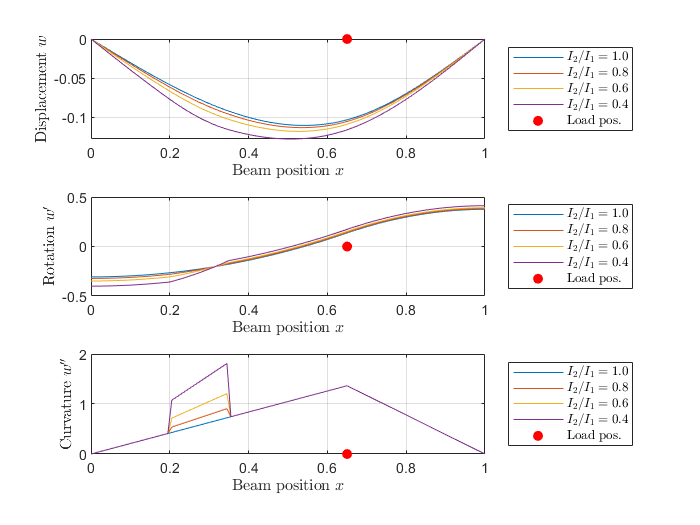

x=0:.005:1;
d_F=.65;
F=6;
E=1;
L=1;
I1=[1.0 1.0 1.0 1.0];
I2=[1.0 0.8 0.6 0.4];
b=[.2 .35];

  W=zeros(length(I1),length(x));
 dW=zeros(length(I1),length(x));
ddW=zeros(length(I1),length(x));

for ii=1:length(I1)
    [w,dw,ddw] = oneFieldBeam(x, E, L, d_F, F, [I1(ii) I2(ii)], b);
      W(ii,:)=  w;
     dW(ii,:)= dw;
    ddW(ii,:)=ddw;
end

figure
subplot(3,1,1)
hold on
for ii=1:length(I1)
    plot(x,W(ii,:))
end
scatter(d_F,0,'r','filled')
ylabel('Displacement $w$','Interpreter','latex')
xlabel('Beam position $x$','Interpreter','latex')
legend([compose('$I_2/I_1 = %.1f$',I2), 'Load pos.'], ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(3,1,2)
hold on
for ii=1:length(I1)
    plot(x,dW(ii,:));
end
scatter(d_F,0,'r','filled')
xlabel('Beam position $x$','Interpreter','latex')
ylabel('Rotation $w^{\prime}$','Interpreter','latex')
legend([compose('$I_2/I_1 = %.1f$',I2), 'Load pos.'], ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(3,1,3)
hold on
for ii=1:length(I1)
    plot(x,ddW(ii,:));
end
scatter(d_F,0,'r','filled')
xlabel('Beam position $x$','Interpreter','latex')
ylabel('Curvature $w^{\prime\prime}$','Interpreter','latex')
legend([compose('$I_2/I_1 = %.1f$',I2), 'Load pos.'], ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on

clearvars

### Two fields

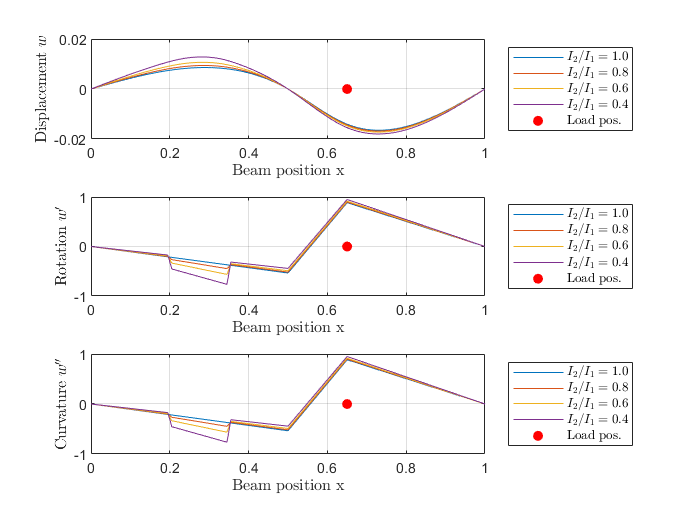

x=0:.005:1;
d_F=.65;
F=12;
E=1;
L=1;
I1=[1.0 1.0 1.0 1.0];
I2=[1.0 0.8 0.6 0.4];
b=[.2 .35];
b_m=.5;

  W=zeros(length(I1),length(x));
ddW=zeros(length(I1),length(x));

for ii=1:length(I1)
    [w,~,ddw] = twoFieldBeam(x, E, L, d_F, F, [I1(ii) I2(ii)], b,b_m);
    W(ii,:)=w;
    ddW(ii,:)=ddw;
end

figure
subplot(3,1,1)
hold on
for ii=1:length(I1)
    plot(x,W(ii,:))
end
scatter(d_F,0,'r','filled')
ylabel('Displacement $w$','Interpreter','latex')
xlabel('Beam position x','Interpreter','latex')
legend([compose('$I_2/I_1 = %.1f$',I2), 'Load pos.'], ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(3,1,2)
hold on
for ii=1:length(I1)
    plot(x,ddW(ii,:));
end
scatter(d_F,0,'r','filled')
xlabel('Beam position x','Interpreter','latex')
ylabel('Rotation $w^{\prime}$','Interpreter','latex')
legend([compose('$I_2/I_1 = %.1f$',I2), 'Load pos.'], ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(3,1,3)
hold on
for ii=1:length(I1)
    plot(x,ddW(ii,:));
end
scatter(d_F,0,'r','filled')
xlabel('Beam position x','Interpreter','latex')
ylabel('Curvature $w^{\prime\prime}$','Interpreter','latex')
legend([compose('$I_2/I_1 = %.1f$',I2), 'Load pos.'], ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on

clearvars

## Homogeneous beam vs. Inhomogeneous beam

### One Field beam (Simple supported beam)

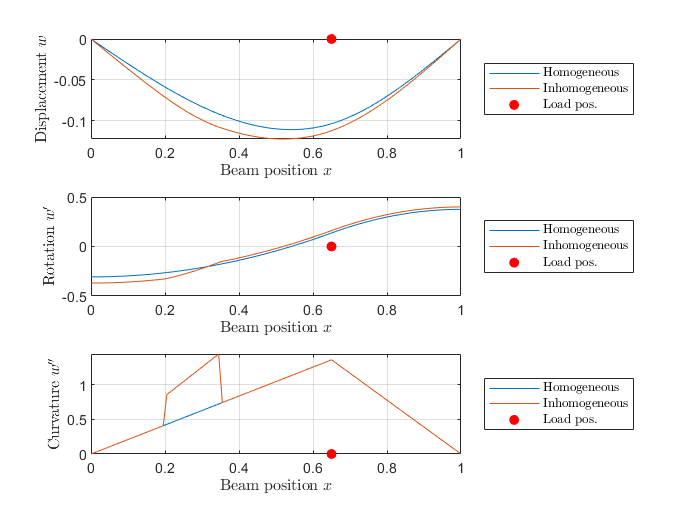

x=0:.005:1;
d_F=.65;
F=6;
E=1;
L=1;
I1=1.0;
I2=0.5;
b=[.2 .35];

[w_hom,dw_hom,ddw_hom] = oneFieldBeam(x, E, L, d_F, F, [I1 I1], b);
[w_inh,dw_inh,ddw_inh] = oneFieldBeam(x, E, L, d_F, F, [I1 I2], b);

figure
subplot(3,1,1)
hold on
plot(x,w_hom,x,w_inh)
scatter(d_F,0,'r','filled')
ylabel('Displacement $w$','Interpreter','latex')
xlabel('Beam position $x$','Interpreter','latex')
legend('Homogeneous','Inhomogeneous', 'Load pos.', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(3,1,2)
hold on
plot(x,dw_hom,x,dw_inh)
scatter(d_F,0,'r','filled')
xlabel('Beam position $x$','Interpreter','latex')
ylabel('Rotation $w^{\prime}$','Interpreter','latex')
legend('Homogeneous','Inhomogeneous', 'Load pos.', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(3,1,3)
hold on
plot(x,ddw_hom,x,ddw_inh)
scatter(d_F,0,'r','filled')
xlabel('Beam position $x$','Interpreter','latex')
ylabel('Curvature $w^{\prime\prime}$','Interpreter','latex')
legend('Homogeneous','Inhomogeneous', 'Load pos.', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on

clearvars

### Two fields

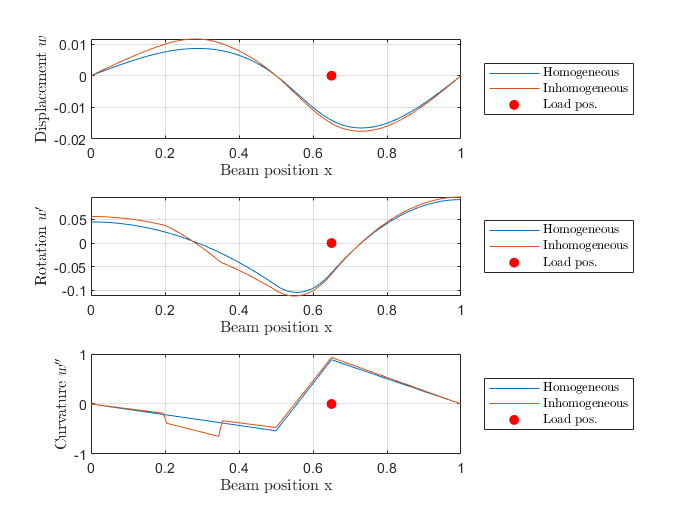

x=0:.005:1;
d_F=.65;
F=12;
E=1;
L=1;
I1=1.0;
I2=0.5;
b=[.2 .35];
b_m=.5;

[w_hom,dw_hom,ddw_hom] = twoFieldBeam(x, E, L, d_F, F, [I1 I1], b, b_m);
[w_inh,dw_inh,ddw_inh] = twoFieldBeam(x, E, L, d_F, F, [I1 I2], b, b_m);

figure
subplot(3,1,1)
hold on
plot(x,w_hom,x,w_inh)
scatter(d_F,0,'r','filled')
ylabel('Displacement $w$','Interpreter','latex')
xlabel('Beam position x','Interpreter','latex')
legend('Homogeneous','Inhomogeneous', 'Load pos.', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(3,1,2)
hold on
plot(x,dw_hom,x,dw_inh)
scatter(d_F,0,'r','filled')
xlabel('Beam position x','Interpreter','latex')
ylabel('Rotation $w^{\prime}$','Interpreter','latex')
legend('Homogeneous','Inhomogeneous', 'Load pos.', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(3,1,3)
hold on
plot(x,ddw_hom,x,ddw_inh)
scatter(d_F,0,'r','filled')
xlabel('Beam position x','Interpreter','latex')
ylabel('Curvature $w^{\prime\prime}$','Interpreter','latex')
legend('Homogeneous','Inhomogeneous', 'Load pos.', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on

clearvars

## Boundary condition cases

### One Field beam 

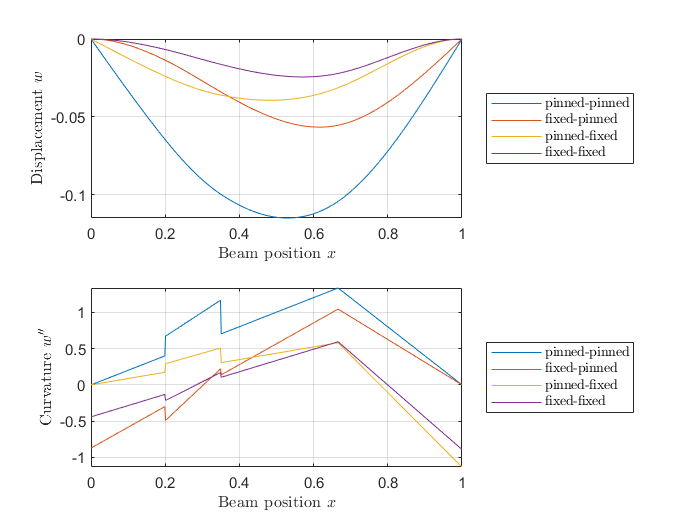

x=0:.001:1;
d_F=.666;
F=6;
E=1;
L=1;
I1=1.0;
I2=0.6;
b=[.2 .35];


[w_pinnedPinned,~,ddw_pinnedPinned] = oneFieldBeam(x, E, L, d_F, F, [I1 I2], b);
[w_fixedPinned ,~,ddw_fixedPinned ] = oneFieldBeam(x, E, L, d_F, F, [I1 I2], b,'fixed' ,'pinned');
[w_pinnedFixed ,~,ddw_pinnedFixed ] = oneFieldBeam(x, E, L, d_F, F, [I1 I2], b,'pinned','fixed');
[w_fixedFixed  ,~,ddw_fixedFixed  ] = oneFieldBeam(x, E, L, d_F, F, [I1 I2], b,'fixed' ,'fixed');

figure
subplot(2,1,1)
hold on
plot(x,w_pinnedPinned)
plot(x,w_fixedPinned)
plot(x,w_pinnedFixed)
plot(x,w_fixedFixed)
ylabel('Displacement $w$','Interpreter','latex')
xlabel('Beam position $x$','Interpreter','latex')
legend('pinned-pinned','fixed-pinned','pinned-fixed','fixed-fixed', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(2,1,2)
hold on
plot(x,ddw_pinnedPinned)
plot(x,ddw_fixedPinned)
plot(x,ddw_pinnedFixed)
plot(x,ddw_fixedFixed)
ylabel('Curvature $w^{\prime\prime}$','Interpreter','latex')
xlabel('Beam position $x$','Interpreter','latex')
legend('pinned-pinned','fixed-pinned','pinned-fixed','fixed-fixed', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on


clearvars

### Two fields

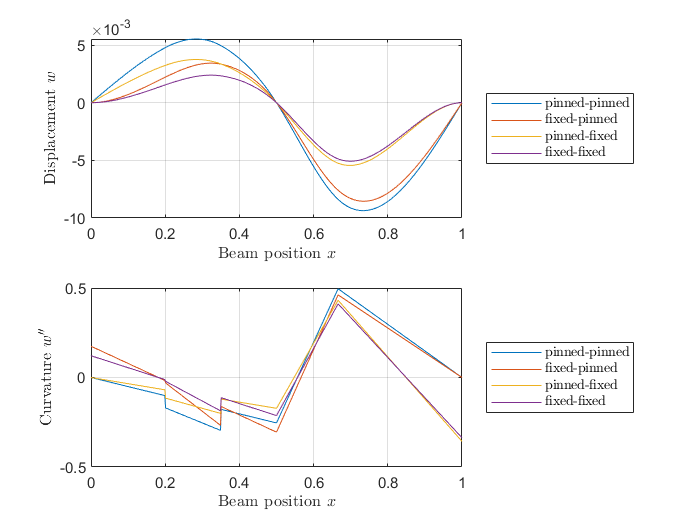

x=0:.001:1;
d_F=.666;
F=6;
E=1;
L=1;
I1=1.0;
I2=0.6;
b=[.2 .35];
b_m=L/2;


[w_pinnedPinned,~,ddw_pinnedPinned] = twoFieldBeam(x, E, L, d_F, F, [I1 I2], b,b_m);
[w_fixedPinned ,~,ddw_fixedPinned ] = twoFieldBeam(x, E, L, d_F, F, [I1 I2], b,b_m,'fixed' ,'pinned');
[w_pinnedFixed ,~,ddw_pinnedFixed ] = twoFieldBeam(x, E, L, d_F, F, [I1 I2], b,b_m,'pinned','fixed');
[w_fixedFixed  ,~,ddw_fixedFixed  ] = twoFieldBeam(x, E, L, d_F, F, [I1 I2], b,b_m,'fixed' ,'fixed');

figure
subplot(2,1,1)
hold on
plot(x,w_pinnedPinned)
plot(x,w_fixedPinned)
plot(x,w_pinnedFixed)
plot(x,w_fixedFixed)
ylabel('Displacement $w$','Interpreter','latex')
xlabel('Beam position $x$','Interpreter','latex')
legend('pinned-pinned','fixed-pinned','pinned-fixed','fixed-fixed', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on
%
subplot(2,1,2)
hold on
plot(x,ddw_pinnedPinned)
plot(x,ddw_fixedPinned)
plot(x,ddw_pinnedFixed)
plot(x,ddw_fixedFixed)
ylabel('Curvature $w^{\prime\prime}$','Interpreter','latex')
xlabel('Beam position $x$','Interpreter','latex')
legend('pinned-pinned','fixed-pinned','pinned-fixed','fixed-fixed', ...
       'Location','eastoutside','Interpreter','latex')
box on
grid on


clearvars